clear 
close all

## Model creation

### INITIAL MODEL

A =[-0.0175  0.173   -9.77    -5.63;
    -0.192   -1.09   -0.846   64.6;
    0        0        0       1;
    0.0081   -0.0738  0.0062  -1.9];
B =[-0.428;4.91;0;4.22];
C=eye(4);
D=[0;0;0;0];

Model=ss(A,B,C,D);
Model.StateName={'u_x','u_z','θ','q'};Model.OutputName={'u_x','u_z','θ','q'}

Model =
 
  A = 
            u_x      u_z
   u_x  -0.0175    0.173
   u_z   -0.192    -1.09
   θ          0        0
   q     0.0081  -0.0738
 
              θ        q
   u_x    -9.77    -5.63
   u_z   -0.846     64.6
   θ          0        1
   q     0.0062     -1.9
 
  B = 
            u1
   u_x  -0.428
   u_z    4.91
   θ         0
   q      4.22
 
  C = 
        u_x  u_z    θ
   u_x    1    0    0
   u_z    0    1    0
   θ      0    0    1
   q      0    0    0
 
          q
   u_x    0
   u_z    0
   θ      0
   q      1
 
  D = 
        u1
   u_x   0
   u_z   0
   θ     0
   q     0
 
Continuous-time state-space model.




%Am =[-0.03   0.166   12.56    37.29;    -0.052   -1.02   -1554.7  -427.82;    0        0       0        1;    0.128    -0.0142 -1335.49 -425.12]

### Reference Model

Am =[-0.03   0.166    125.6     37.29;
     -0.052  -1.02    -1554.7   -427.82;
     0       0        0         1;
     0.128   -0.0142  -1335.49  -425.12];
Bm=[-0138.1;1584.2;0;1361.6];
Cm=eye(4);
Dm=[0;0;0;0];

ModelRerefence=ss(Am,Bm,Cm,Dm);
ModelRerefence.StateName={'u_x','u_z','θ','q'};ModelRerefence.OutputName={'u_x','u_z','θ','q'}

ModelRerefence =
 
  A = 
            u_x      u_z
   u_x    -0.03    0.166
   u_z   -0.052    -1.02
   θ          0        0
   q      0.128  -0.0142
 
              θ        q
   u_x    125.6    37.29
   u_z    -1555   -427.8
   θ          0        1
   q      -1335   -425.1
 
  B = 
            u1
   u_x  -138.1
   u_z    1584
   θ         0
   q      1362
 
  C = 
        u_x  u_z    θ
   u_x    1    0    0
   u_z    0    1    0
   θ      0    0    1
   q      0    0    0
 
          q
   u_x    0
   u_z    0
   θ      0
   q      1
 
  D = 
        u1
   u_x   0
   u_z   0
   θ     0
   q     0
 
Continuous-time state-space model.



## Step responses

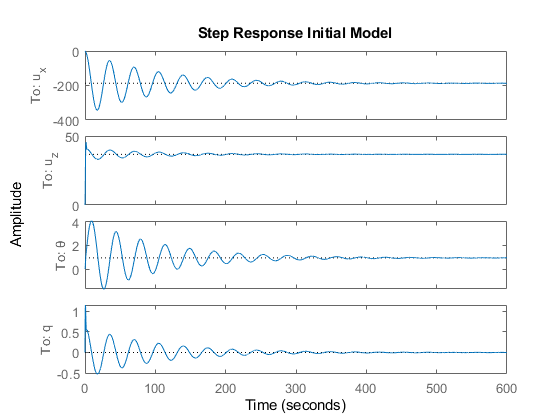

figure(1)
step(Model)
title("Step Response Initial Model")

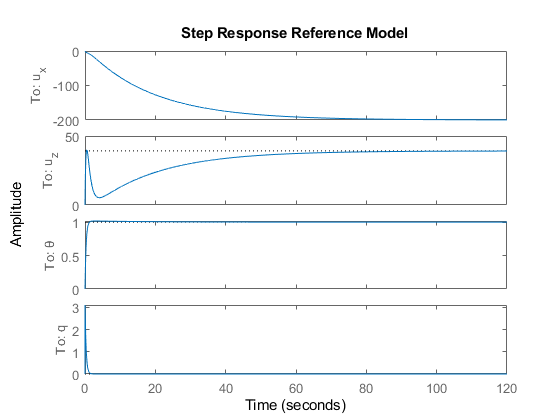

figure(2)
step(ModelRerefence)
title("Step Response Reference Model")

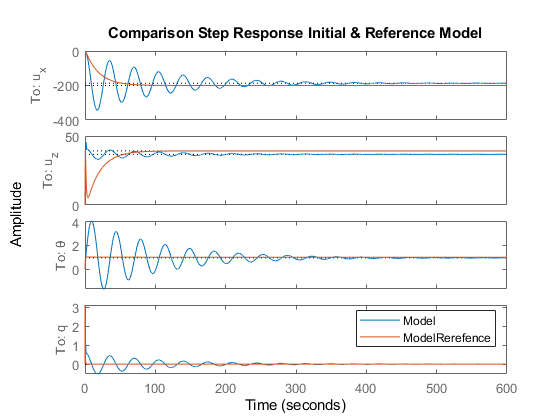

figure(3)
step(Model)
hold on
step(ModelRerefence)
hold off
legend
title("Comparison Step Response Initial & Reference Model")

## MRAC

### GAINS

Kr_i = B\Bm

Kr_i = 322.6504

Kx_i= (B)\(Am-A)

Kx_i =     0.0285    0.0142 -316.4669 -100.2891



ModelMRAC=ss(A+B*Kx_i, B*Kr_i, eye(4),0);
ModelMRAC.StateName={'u_x','u_z','θ','q'};
ModelMRAC.OutputName={'u_x','u_z','θ','q'}

ModelMRAC =
 
  A = 
             u_x       u_z
   u_x  -0.02969    0.1669
   u_z  -0.05219     -1.02
   θ           0         0
   q      0.1283  -0.01384
 
               θ         q
   u_x     125.7     37.29
   u_z     -1555    -427.8
   θ           0         1
   q       -1335    -425.1
 
  B = 
            u1
   u_x  -138.1
   u_z    1584
   θ         0
   q      1362
 
  C = 
        u_x  u_z    θ
   u_x    1    0    0
   u_z    0    1    0
   θ      0    0    1
   q      0    0    0
 
          q
   u_x    0
   u_z    0
   θ      0
   q      1
 
  D = 
        u1
   u_x   0
   u_z   0
   θ     0
   q     0
 
Continuous-time state-space model.



### MRAC VS REFERENCE MODEL

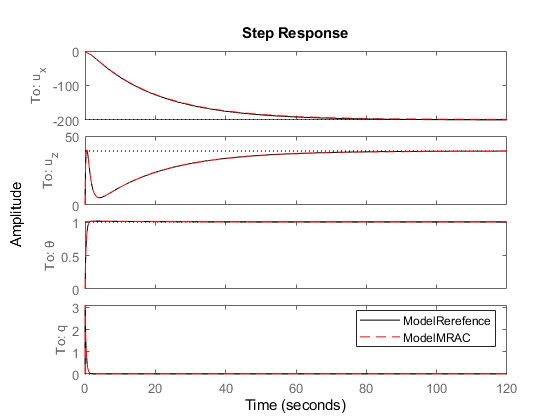

figure()
step(ModelRerefence,"k")
hold on
step(ModelMRAC,"r--")
hold off
legend

### THETA

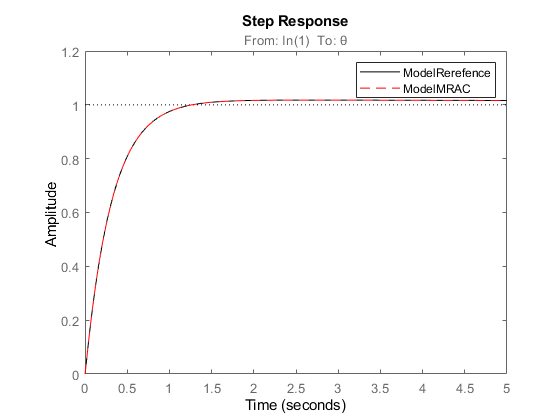

figure()
step(ModelRerefence(3,:),"k")
hold on
step(ModelMRAC(3,:),"r--")
hold off
legend("ModelRerefence","ModelMRAC")
xlim([0 5])

### PULSE TRAIN

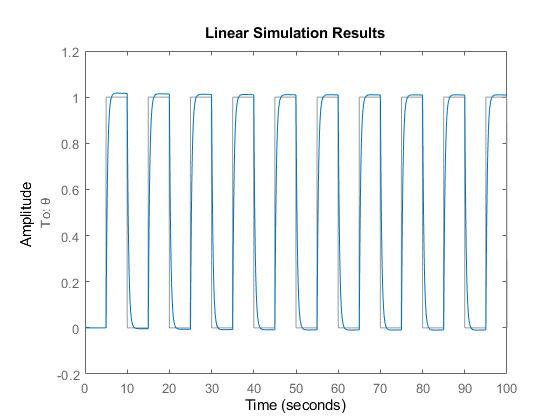

[u,t] = gensig("square",10,100,0.05); %tren de pulsos
lsim(ModelMRAC(3,:),u,t)